% a1 = 1; a2 = 2;
% w1 = 3; w2 = 4;
% phi1 = 5; phi2 = 6;

a1 = 1;
a2 = 3;
w1 = 3;
w2 = 5;
phi1 = 2;
phi2 = 7;

T = 10; dt_cont = 0.01;
t_cont = 0 : dt_cont : T;

y = @(t) a1 * sin(t .* w1 + phi1) + a2 * sin(t.* w2 + phi2);

y_cont = arrayfun(y, t_cont);

dt_disc = 0.5;
t_disc = 0 : dt_disc : T;

y_disc = arrayfun(y, t_disc);

V = 1/dt; dv = 1/T;
v = -V/2 : dv : V/2;

numerical_fourier = zeros(size(v));
for k = 1 : length(t)
    numerical_fourier(k) = trapz(t_cont, y_cont.* exp(-2*pi*1i .* v(k) .* t_cont));
end

fft_fourier = fftshift(fft(y_cont));

y_restored = zeros(size(t_cont));

for n = 1 : length(t_disc)
    y_restored = y_restored + y(n / (2 * B)) * sinc(2*B*(t - (n / (2*B))));
end

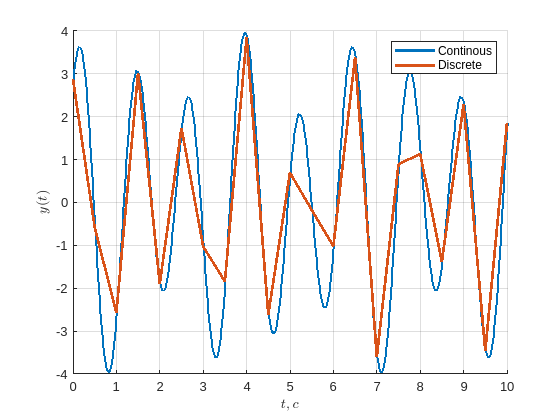

figure;
hold on;
plot(t_cont, y_cont, 'LineWidth', 2);
plot(t_disc, y_disc, 'LineWidth', 2);
hold off;

ylabel({"$y(t)$"}, 'Interpreter', 'latex');
xlabel({"$t, c$"}, 'Interpreter', 'latex');
legend({"Continous", "Discrete"});
grid on;

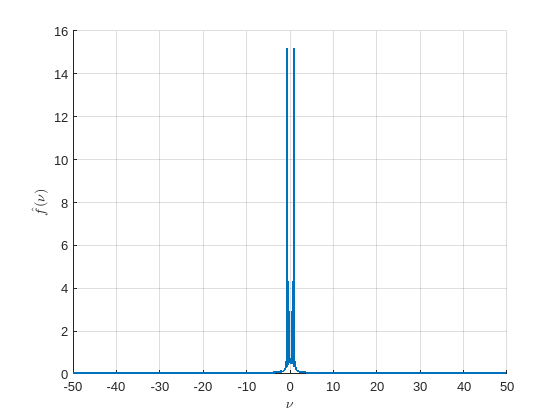

figure;
hold on;
plot(v, abs(numerical_fourier), 'LineWidth', 2);
% plot(v, abs(fft_fourier), 'LineWidth', 2);
hold off;

ylabel({"$\hat{f}(\nu)$"}, 'Interpreter', 'latex');
xlabel({"$\nu$"}, 'Interpreter', 'latex');
% legend({"Numerical", "FFT"});
% legend({"Real", "Imag"});
grid on;